## Exercício 2

**(a)**

n = 20;
m = 100;
N = 1000;
contagem = 0;
alvos = randi(m,n,N);       % ele acertou no alvo "número que está na matriz".
                            % caso esse número apareça repetido naquela
                            % coluna quer dizer que o mesmo alvo foi
                            % acertado mais que uma vez o que não pode, por
                            % isso é usada a função unique() que ordena (o 
                            % que aqui não importa) e remove os repetidos
                            % assim, caso o mesmo alvo seja acertado, o
                            % tamanho dessa coluna deixa de ser 20, o que
                            % significa que um alvo vou acertado mais que
                            % uma vez
for a = 1:N
    if length(alvos(:,a)) == length(unique(alvos(:,a)))
        contagem = contagem + 1;
    end
end

prob = contagem/N

prob = 0.1410

**(b)**

alvos = randi(m,n,N);

for a = 1:N    
    if length(alvos(:,a)) == length(unique(alvos(:,a)))
        contagem = contagem + 1;
    end
end

prob = 1-contagem/N

prob = 0.7230

**(c)**

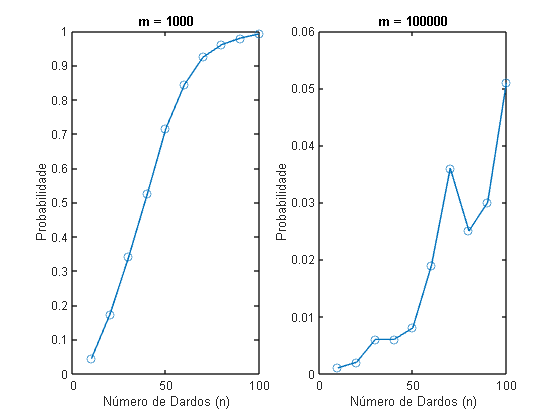

nValores = 10:10:100;
mValores = [1000,100000];
N = 1000;
prob = zeros(length(nValores),length(mValores));

for j = 1:length(mValores)
    m = mValores(j);
    for i = 1:length(nValores)
        n = nValores(i);
        contagem = 0;
        alvos = randi(m,n,N);
        for a = 1:N    
            if length(alvos(:,a)) == length(unique(alvos(:,a)))
                contagem = contagem + 1;
            end
        end
        prob(i ,j) = 1-contagem/N;
    end
end
figure;
subplot(1, 2, 1);
plot(nValores, prob(:, 1), '-o');
title('m = 1000');
xlabel('Número de Dardos (n)');
ylabel('Probabilidade');

subplot(1, 2, 2);
plot(nValores, prob(:, 2), '-o');
title('m = 100000');
xlabel('Número de Dardos (n)');
ylabel('Probabilidade');

**(d)**

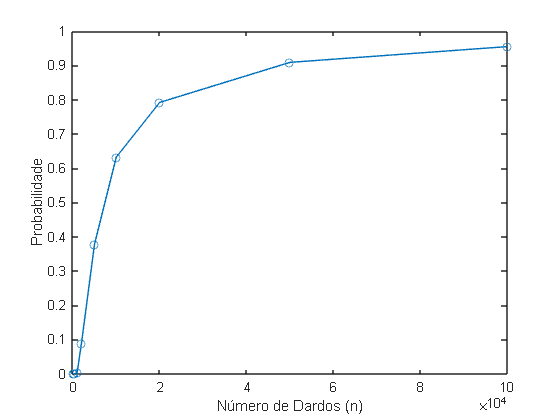

n = 100;
mValores = [200, 500, 1000, 2000, 5000, 10000, 20000, 50000, 100000];
N = 1000;
prob = zeros(length(mValores),1);

for j = 1:length(mValores)
    m = mValores(j);
    contagem = 0;
    alvos = randi(m,n,N);
    for a = 1:N    
        if length(alvos(:,a)) == length(unique(alvos(:,a)))
            contagem = contagem + 1;
        end
    end
    prob(j) = contagem/N;
end
figure;
plot(mValores, prob, '-o');
xlabel('Número de Dardos (n)');
ylabel('Probabilidade');